# Apuntes de clase - Variables aleatorias discretas

Herramientas Matemáticas para el manejo de la información

Sesión 5 - 5 de marzo de 2026

# Solución de la tarea 5

Vector de resultados:

x = [1/32,1/16,1/8,1/4,1/2,1]

x =     0.0312    0.0625    0.1250    0.2500    0.5000    1.0000


Vector de probabilidades:

pdf = [0.001,0.2,0.25,0.3,0.2,0.049]

pdf =     0.0010    0.2000    0.2500    0.3000    0.2000    0.0490


Límites de los intervalos:

format short;
cdf = cumsum(pdf)

cdf =     0.0010    0.2010    0.4510    0.7510    0.9510    1.0000


Número aleatorio uniformemente distribuido, con parámetros $a=0$ y $b=1$.

format short;
p = rand

p = 0.1712

for n = 1:numel(cdf)
    if p<cdf(n)
        y = x(n);
        break;
    end
end

Posición del resultado:

n

n = 2

`n`-ésimo elemento del vector `x:`

format rat;
y = x(n)

y =        1/16    


Solución vectorizada:

n = sum(cdf<p)+1

n =        2       


y = x(n)

y =        1/16    


## Ejemplo de la moneda

format short;
va([0,1],[0.5,0.5])

ans = 1

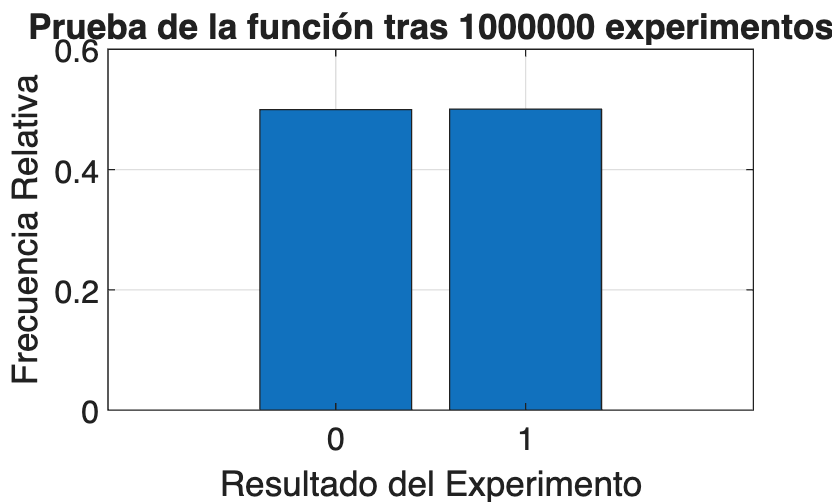

ans =     0.4995    0.5005


pruebava([0,1],[0.5,0.5],1000000)

## Ejemplo del partido

va([0,1,3],[0.5,0.1,0.4])

ans = 0

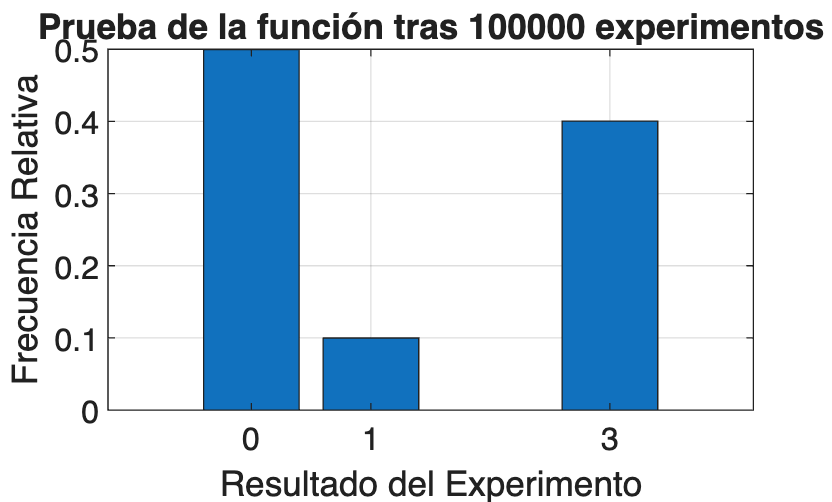

ans =     0.4996    0.0999    0.4005


pruebava([0,1,3],[0.5,0.1,0.4],100000)

## Ejemplo del dado

va([1,2,3,4,5,6],[1/6,1/6,1/6,1/6,1/6,1/6])

ans = 1

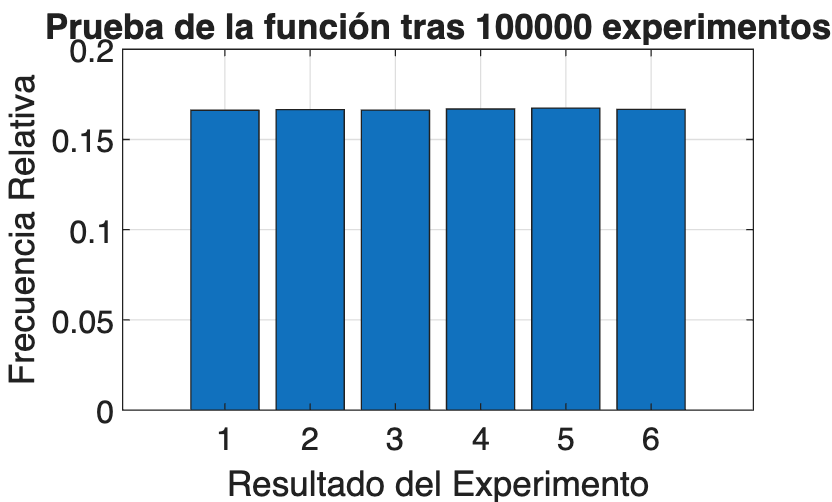

ans =     0.1662    0.1666    0.1663    0.1669    0.1673    0.1667


pruebava([1,2,3,4,5,6],[1/6,1/6,1/6,1/6,1/6,1/6],100000)

# Función `va `

La función `va` se puede sobrecargar para que no solo genere un único resultado:

help va

  Función va(x,p,filas,columnas)
  La función va(x,p,filas,columnas) retorna una matriz de tamaño filas por
  columnas. Los elementos de la matriz pertenecen a los números indicados
  en el vector x. La probabilidad de ocurrencia de cada elemento de x se
  debe indicar en el vector p.
 
  Ejemplo:
 
  x = [1 2 3];
  p = [0.2 0.3 0.5];
  va(x,p,1,10)
 
  Retorna un vector fila de 10 elementos, que contiene aleatoriamente los
  números del 1 al 3. En promedio, dos elementos deberían ser 1, tres
  elementos deberían ser 2 y cinco deberían ser 3
 
  Ejemplo:
 
  x = [-2 1];
  p = [0.3 0.7];
  va(x,p,10)
 
  Retorna una matriz de 10x10, que contiene aleatoriamente los números -2
  y 1. En promedio, treinta elementos deberían ser -2 y setenta deberían
  ser iguales a 1
 
  Ejemplo:
 
  x = [0 1 3];
  p = [0.2 0.3 0.5];
  va(x,p)
 
  Retorna aleatoriamente uno de los números que pertenecen al vector x. Las
  

## Fecha de presentación del primer trabajo grupal

26 de marzo de 2026

# Para recordar...

Una variable aleatoria "no es variable, ni es aleatoria". Es una función que mapea (de manera determinista) los elementos de $\Omega$ en el conjunto de los números reales.


$$X:\Omega \to \mathbb{R}$$


Se llama variable porque es la variable independiente de otras funciones que dan información de la probabilidad, como lo son: la función de densidad de probabilidad o la esperanza matemática. Se llama aleatoria porque cada número real asignado proviene de un resultado del experimento aleatorio.

# Función de Distribución Acumulativa

Sea $X$ una variable aleatoria:


$$X:\Omega \to \mathbb{R}$$


Se define la función de distribución acumulativa:


$$F_X(x) := P[X \leq x] \quad \forall x \in \mathbb{R}$$


## Estudiantes que resolvieron correctamente el primer ejercicio en clase

July Paulina Muñoz

Stiven Rodríguez

Sonia Chivatá

María Camila

## Observaciones

- Si la variable aleatoria es discreta, la función de distribución acumulativa (CDF) es escalonada.

- La función de distribución acumulativa empieza en cero y termina en uno.

- La función de distribución acumulativa es monótonamente no decreciente.


$$F_X(-\infty) = 0$$



$$F_X(\infty) = 1$$



$$\frac{d}{dx}F_X(x)\geq 0$$


# Funciones

function fr = pruebava(x,pdf,repeticiones)

    resultados = zeros(1,repeticiones);
    for n = 1:repeticiones
        resultados(n) = va(x,pdf);
    end
    
    total = numel(x);
    
    fr = zeros(1,total);
    
    for n = 1:total
        fr(n)= sum(resultados == x(n))/repeticiones;
    end
    
    bar(x,fr)
    colormap(summer)
    set(gca,'Fontsize',12);
    xlabel('Resultado del Experimento');
    ylabel('Frecuencia Relativa');
    title(['Prueba de la función tras ',...
        num2str(repeticiones),' experimentos']);
    grid on;
    set(gcf,'Color','White');
end